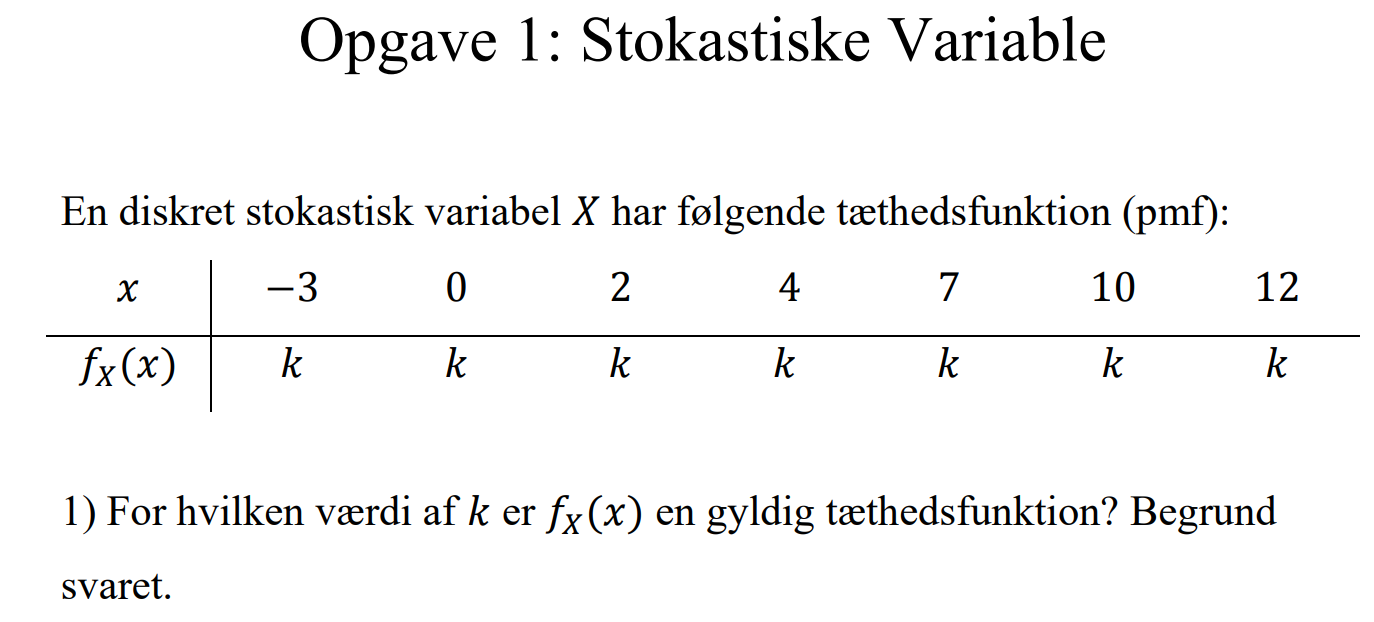

clearvars

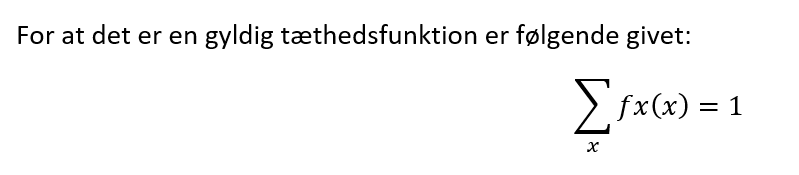

syms k
x = [-3 0 2 4 7 10 12];
k = solve(k*length(x)== 1 , k)

$$k = \frac{1}{7}$$

fx = [k k k k k k k];
plot(x,fx)

title('Tæthedsfunktion')
xlabel('x')
ylabel('y')


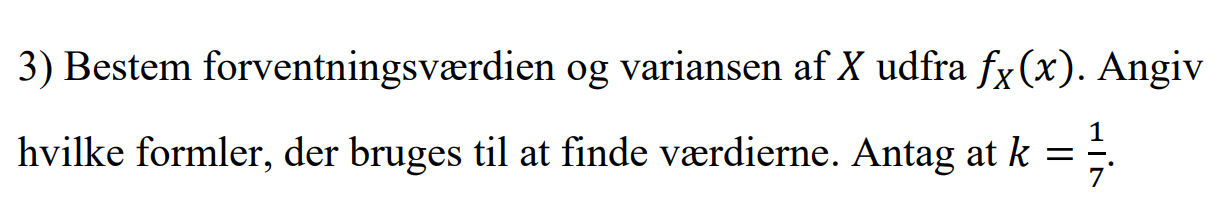

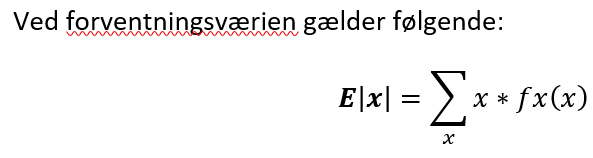

Ex= sum(x.*fx)

$$Ex = \frac{32}{7}$$

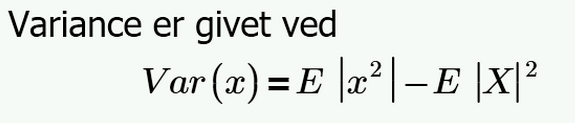

Ex2= sum(x.^2.*fx)

$$Ex2 = 46$$

var = Ex2 - Ex^2

$$var = \frac{1230}{49}$$

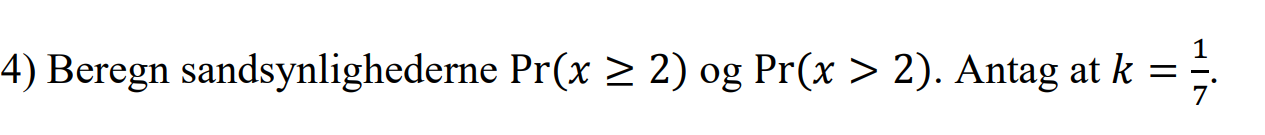

Pr1 = sum(fx(x>=2))

$$Pr1 = \frac{5}{7}$$

Pr2 = sum(fx(x>2))

$$Pr2 = \frac{4}{7}$$

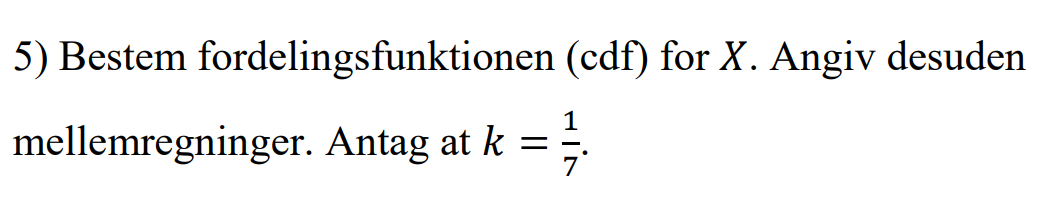

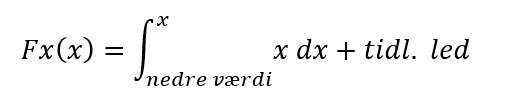

syms x
Fx(x) = piecewise( x < -3, 0, ...
              -3 <= x < 0, 1/7, ...
              0 <= x < 2, 2/7, ...
              2 <= x < 4, 3/7, ...
              4 <= x < 7, 4/7, ...
              7 <= x < 10, 5/7, ...
              10 <= x < 12, 6/7, ...
              12 <= x, 7/7)

$$Fx(x) = \left\{ \begin{array}{cl} 0 & \text{ if }x<-3\\ \frac{1}{7} & \text{ if }x\in \left[-3,0\right)\\ \frac{2}{7} & \text{ if }x\in \left[0,2\right)\\ \frac{3}{7} & \text{ if }x\in \left[2,4\right)\\ \frac{4}{7} & \text{ if }x\in \left[4,7\right)\\ \frac{5}{7} & \text{ if }x\in \left[7,10\right)\\ \frac{6}{7} & \text{ if }x\in \left[10,12\right)\\ 1 & \text{ if }12\leq x \end{array}\right.$$

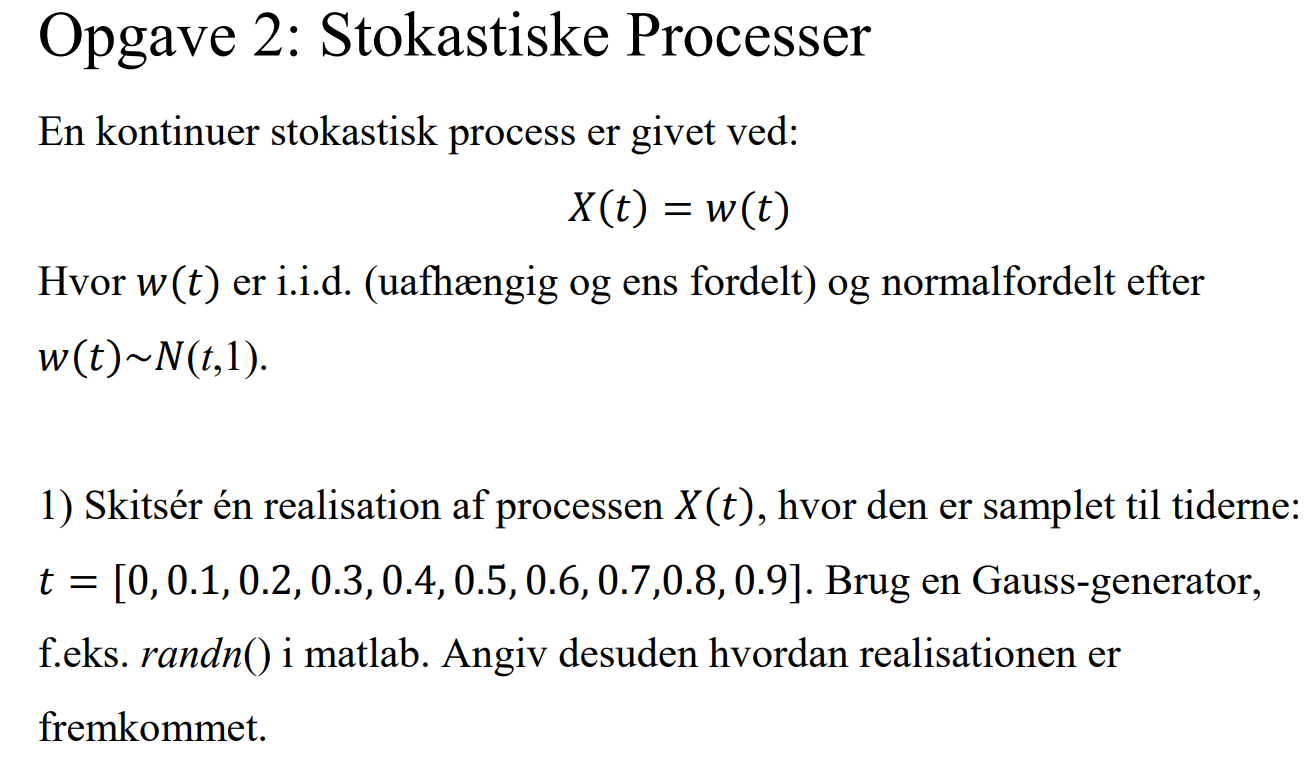

close all
t = 0:0.1:0.9;
mean = t; variance = 1; sigma = sqrt(variance);
w = normrnd(mean, sigma, [1 length(t)])

w =     1.4180   -0.2546    1.2219    0.9018   -0.1973    2.4134    1.4734    1.6026   -0.1096    0.2529


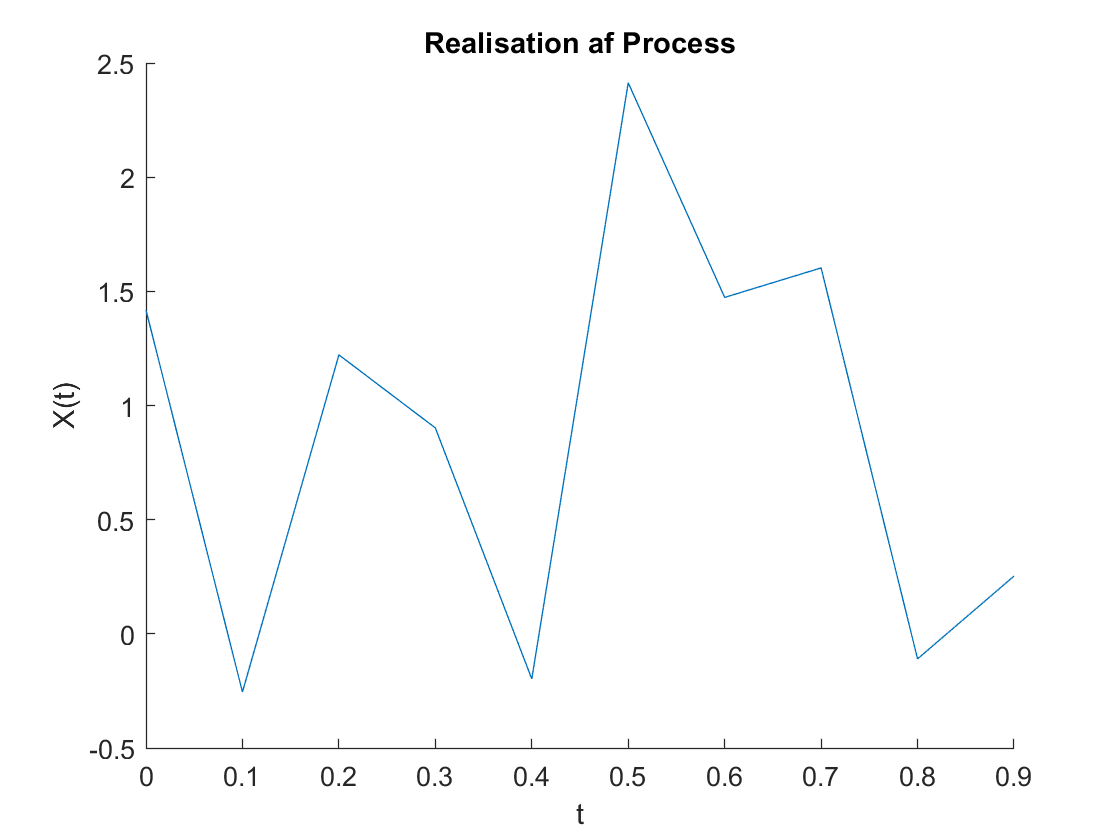

figure(1)
hold on;
xlabel("t"); ylabel("X(t)"); title("Realisation af Process");
plot(t, w)

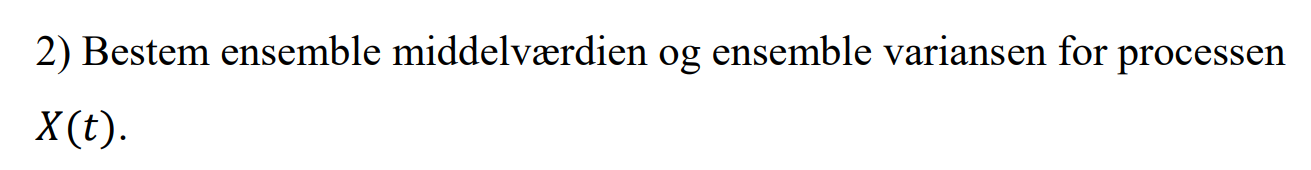

 Ensemble middelværdi ved w(t)~N(t,1) er t pga normalfordelingsfunktionen, 

 0 ved den givne stokastiske process

EnsembleMean = t + 0

EnsembleMean =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000


 ensemble variansen ved w(t)~N(t,1) er 1 pga normalfordelingsfunktionen

 og +0 ved den givne stokastiske process

EnsembleVar = 1 + 0

EnsembleVar = 1

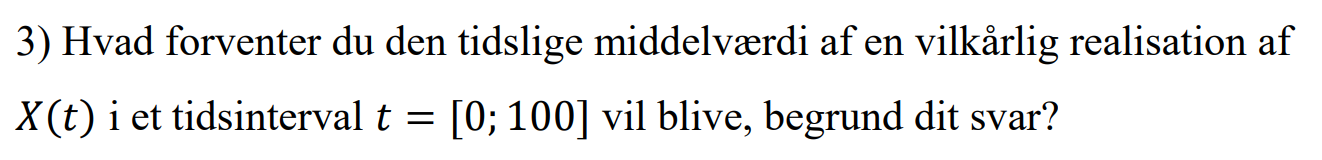

t = 0:1:100;
mean = t; variance = 1; sigma = sqrt(variance);
w = normrnd(mean, sigma, [1 length(t)])

w =     0.6464    2.1998    1.9736    4.7119    3.8722    5.7181    6.0034    8.0940    7.6729    8.9686    8.4917   11.3023   12.0897   13.5281   14.3382   14.3307   16.6640   19.6102   17.3585   19.9323   19.4222   20.0916   20.8772   23.5754   24.0332   25.8737   25.8100   25.8246   27.8017   28.9262   30.6124   29.7896   30.1569   33.4588   33.2235   34.5092   36.5504   37.0183   38.1649   40.1843   41.0659   41.0036   41.4683   41.8062   44.3158   47.3131   47.0471   47.2250   46.9021   47.7741


clear mean
mean(w)

ans = 50.0930

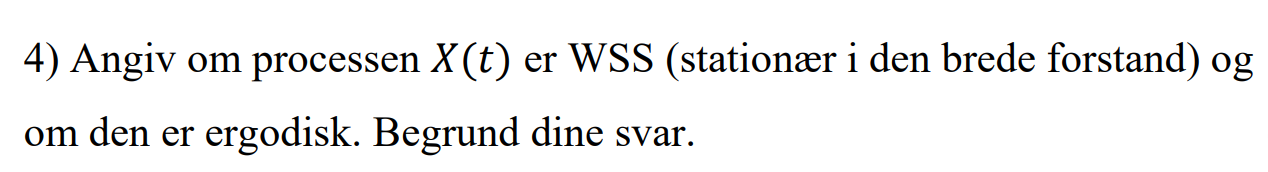

Da processen er afhængig af tiden, og at middelværdien og variansen ændrer sig over tid, så kan vi konstanter at processen ikke er stationær.

Da processen ikke er stationær, så kan den heller ikke være ergodisk. 

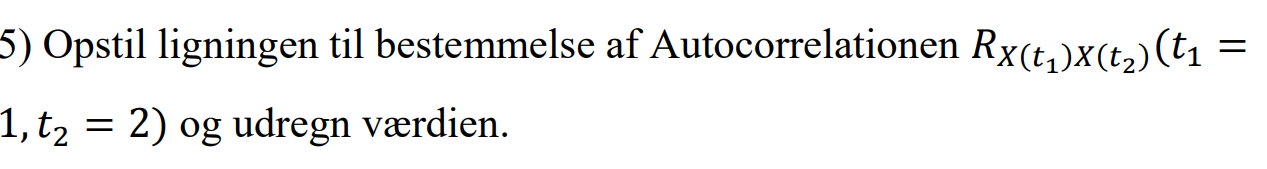

t1 = 1; t2=2;
E_T1 = 1 + 0;
E_T2= 2 + 0;
E_T1 * E_T2

ans = 2

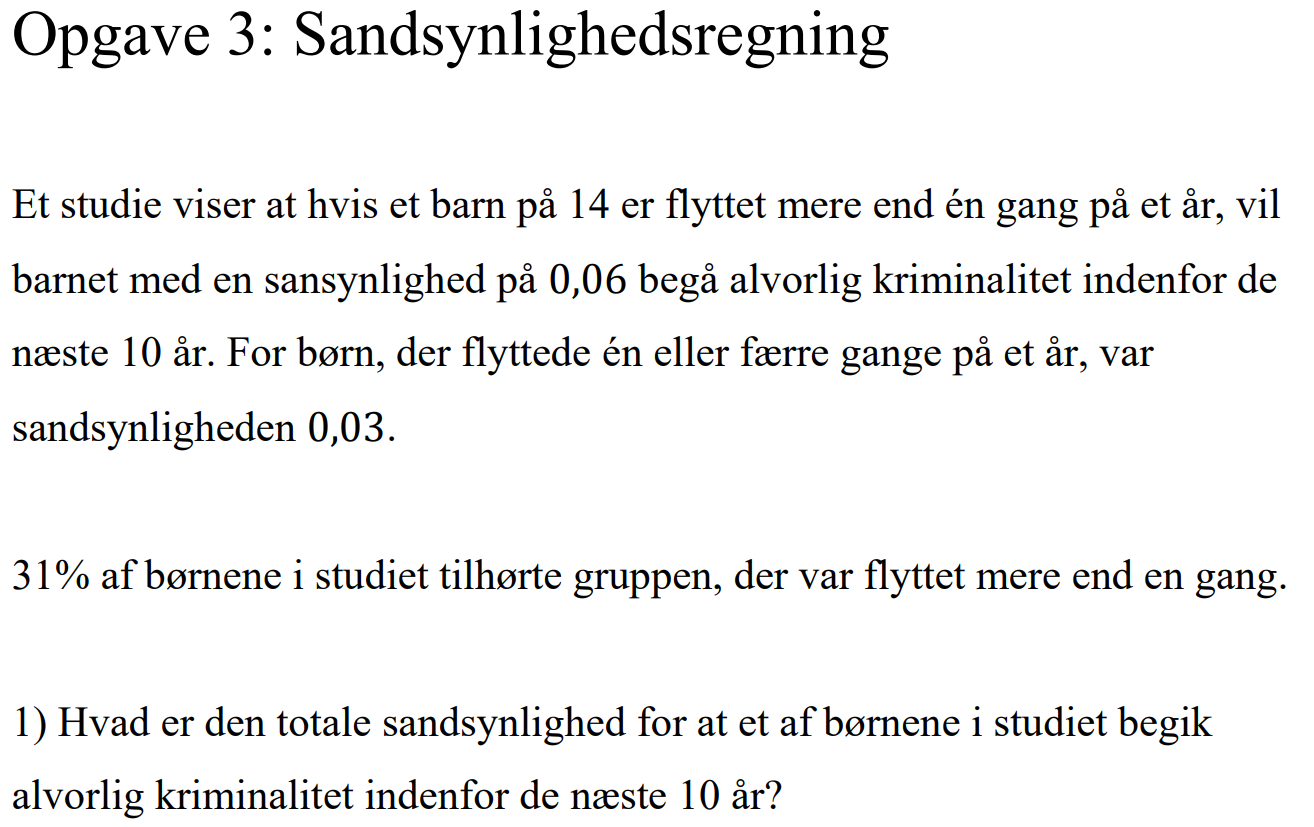

Hændelse A : Barn er flyttet mere end en gang

Hændelse B : Begår kriminalitet

format
Pr_B_A = 0.06;
Pr_B_NOT_A = 0.03;
Pr_a = 0.31;
Pr_not_a = 1-Pr_a;

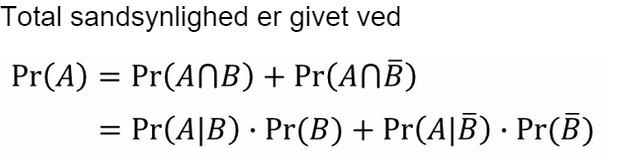

Pr_b = Pr_B_A*Pr_a+Pr_B_NOT_A*Pr_not_a

Pr_b = 0.0393

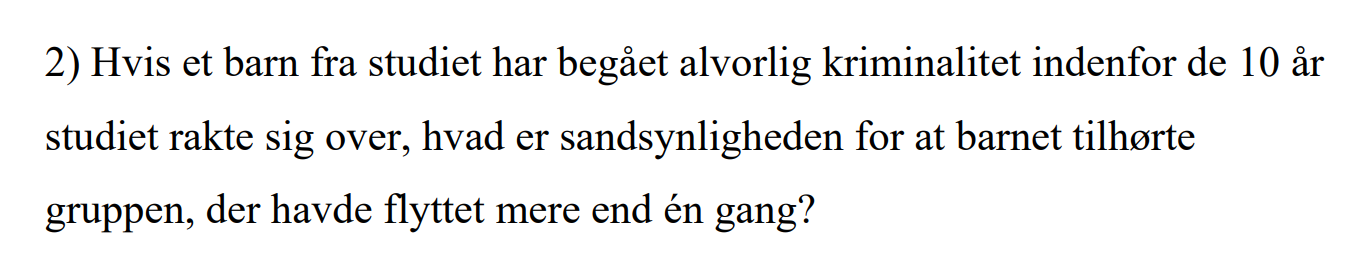

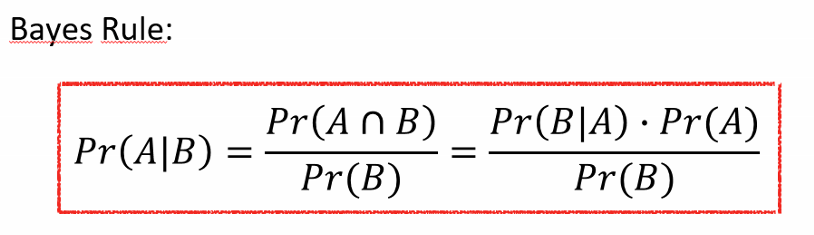

SandsynlighedTilhorteGruppe = (Pr_B_A*Pr_a)/Pr_b

SandsynlighedTilhorteGruppe = 0.4733

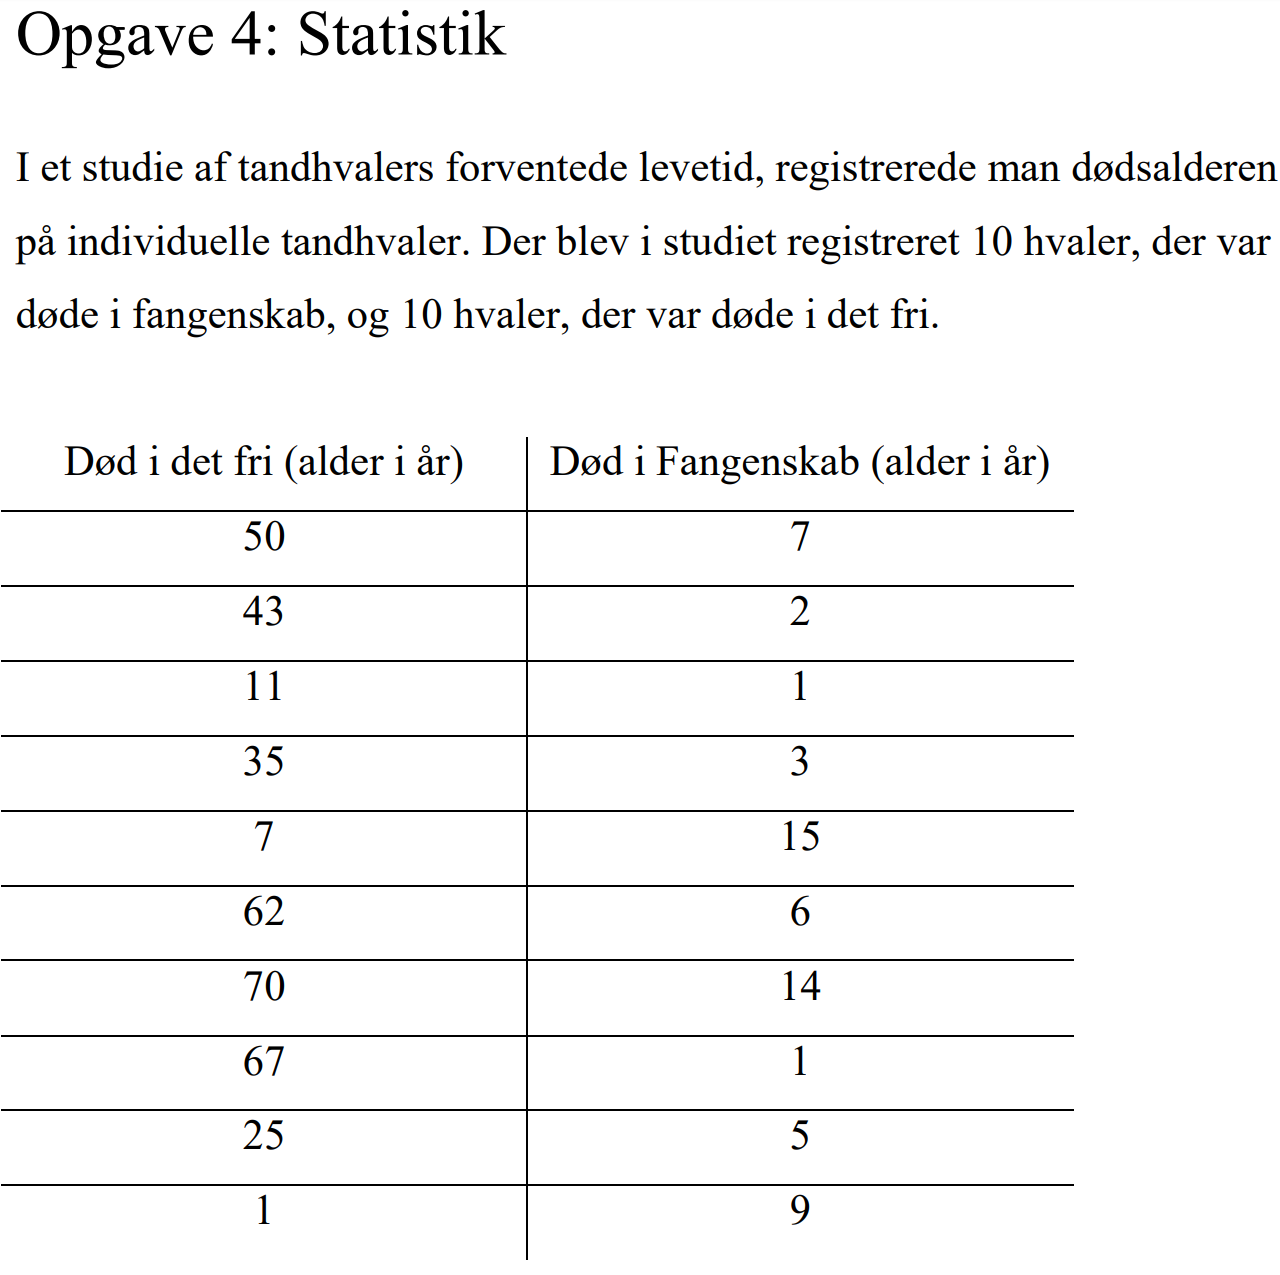

fri = [50 43 11 35 7 62 70 67 25 1 ];
fange = [7 2 1 3 15 6 14 1 5 9];

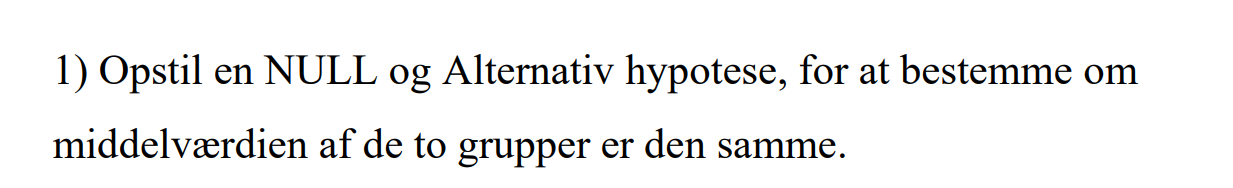

Null hypothesis. Brugt som testen af ingen forskel.


$$H_0 =\mu 1=\mu 2$$


Alternanive hypotese


$$H_1 =\mu 1\not= \mu 2$$


Testen være udføres uparrat, da dataens subject ( fangenskab eller fri) er to forskellige ting. 

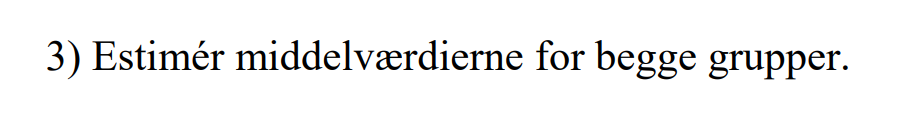

friMean = mean(fri)

friMean = 37.1000

fangeMean = mean(fange)

fangeMean = 6.3000

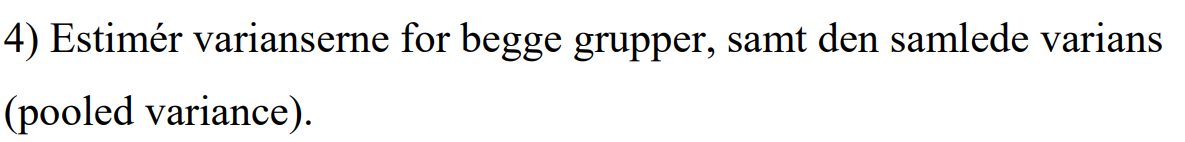

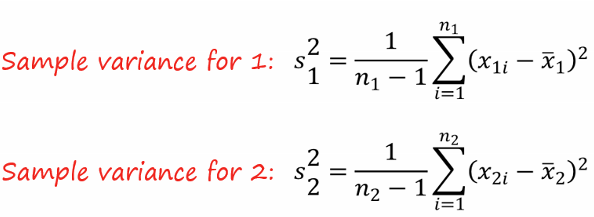

 S2_fange = (1/(length(fange)-1)) * sum((fange-fangeMean).^2)

S2_fange = 25.5667

 S2_fri = (1/(length(fri)-1)) * sum((fri-friMean).^2)

S2_fri = 648.7667

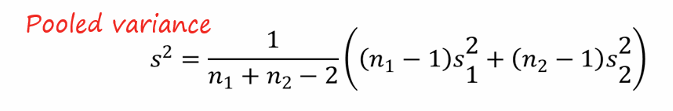

 
 PooledVar = ...
     (((length(fange)-1) * S2_fange) +...
     ((length(fri)-1) * S2_fri)) /...
     (length(fange)+length(fri)-2)

PooledVar = 337.1667

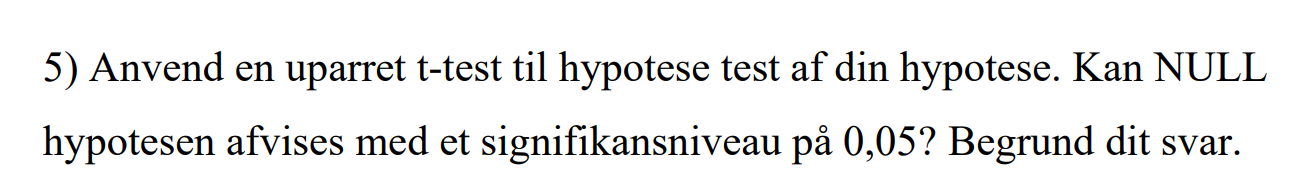

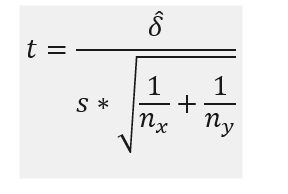

t = abs(friMean-fangeMean)/(sqrt(PooledVar)*sqrt((1/length(fri))+(1/length(fange))))

t = 3.7507

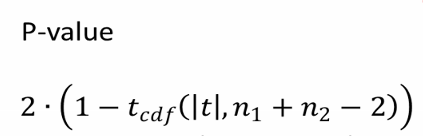

pval = 2*(1-tcdf(abs(t),(length(fri)+length(fange))-2))

pval = 0.0015

Da pval er mindre end 0.05 så afvises hypotesen. 

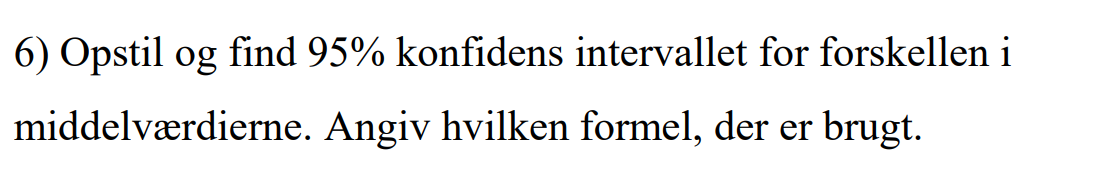

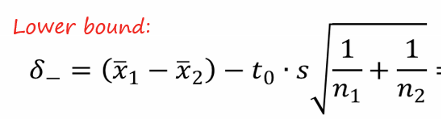

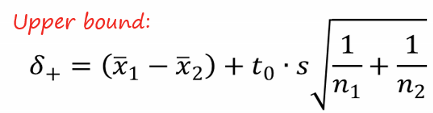

n1 = length(fri)

n1 = 10

n2 = length(fange)

n2 = 10

middel = abs(friMean-fangeMean)

middel = 30.8000

t0=tinv(0.975,(n1+n2-2))

t0 = 2.1009

koefMinus = middel-t0*sqrt(PooledVar)*sqrt((1/n1)+(1/n2))

koefMinus = 13.5477

koefPositiv = middel+t0*sqrt(PooledVar)*sqrt((1/n1)+(1/n2))

koefPositiv = 48.0523